# Grover's Algorithm to solve Sudoku

## Classic method, random brute-force

Sudoku is a simple puzzle game. We have a 9x9 matrix with some specific numbers already placed in certain positions. The aim of the game is to complete the matrix using only number from 1 to 9, but following this three rules:

- Every row must contain all numbers from 1 to 9 without repetition.

- every colum need all number from 1 to 9 whitout repetition.

- The 9x9 matrix is divided into nine 3x3 subgrids and for every square we need all number from 1 to 9 whitout repetition.

The input numbers in the Sudoku are set to ensure only one possible solution. 

An example of a Sudoku:

We begin by creating a matrix where empty positions are represented by zeros. In this example, a simplified version is used to reduce computation time.

puzzle = [3 8 6 2 5 4 1 7 9; 
    5 1 9 6 8 7 3 2 4; 
    7 2 4 9 1 3 5 8 6; 
    6 5 2 8 9 1 4 3 7; 
    9 4 3 7 2 6 8 1 5; 
    1 7 8 3 4 5 9 6 2; 
    2 3 1 4 0 0 0 0 8; 
    4 6 7 5 3 0 0 9 1;
    8 9 5 1 6 0 0 0 3];


this function plot the sudoku: 

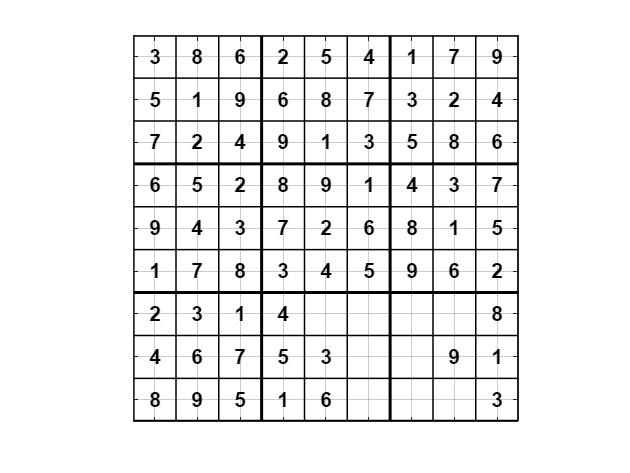



plotSudoku(puzzle);

Now we want to implement the algorithm effectively by transform the matrix into a graph where each node represents a position in the matrix, every node is connected whit an edge to all other nodes in the same row/ colum and 3X3 subgrids. The edges represent Sudoku constraints, if two nodes are connected, they cannot have the same value.

What i need to do is to build the Graph and correctly connect all the nodes


A= [zeros(81)]; % thsi is the adjacency matrix for the graph
for i = 1 : 81
    for j = 1 : 81
        if(floor((i-1)/9) == floor((j-1)/9) && i~=j) % connect all the nodes on the same row of the sudoku
            A(i,j) = 1;
        end
        if (mod(i,9) == mod(j,9) && i~=j) % connect all the nodes on the same column of the sudoku
            A(i,j) = 1;
        end
        if (floor((mod(i,9) - 1)/3) == floor((mod(j,9)- 1)/3) && i~=j) % connect all the nodes in the same subgrid of the sudoku
            if(floor((i-1)/9) <= 2)
                if(floor((j-1)/9) <= 2)
                    A(i,j) = 1;
                end
            elseif (floor((i-1)/9) <= 5)
                if((floor((j-1)/9) <=5) && (floor((j-1)/9) >= 3))
                    A(i,j) = 1;
                end
            elseif(floor((j-1)/9) >= 6)
                A(i,j) =1;
            end
        end
    end
end

A = max(A, A'); % i need symmetric matrix because the graph have only bidirectional edges

Sudoku_Graph = graph(A);


An easy way to demonstrate the power of Grover's algorithm is to try every possible input and verify if the solution is correct until you find the chosen one:

For each node, we associate an object with two properties:

- `Value`: the number in the Sudoku cell.

- `State`: a boolean indicating whether the node is editable (`true`) or fixed (`false`). This is particularly useful when adapting the algorithm for Grover’s search.


Solved = 0;

while (Solved == 0)
    
    Try = rand_option(puzzle);

    % object assigment

    node_data = repmat(Node_sudoku(0, 1), 81, 1); % i allocate 1 array for the data in the graph

    for i = 1:9
        for j = 1:9
            idx = (i - 1) * 9 + j;  % linear index that reads rows and column
            node_data(idx) = Node_sudoku(Try(i,j), 0);
        end
    end

    Sudoku_Graph.Nodes.Data = node_data;

    

Now, I need to verify if the current try is correct or not, using the graph above, basically, I just need to check whether any connected nodes have the same value

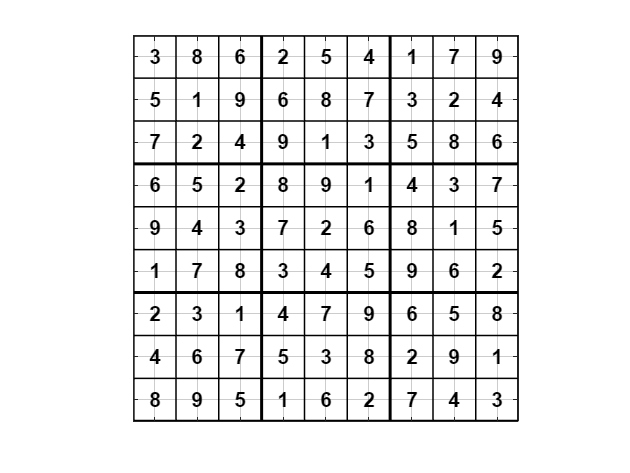


    conflict_count = 0;



    for k = 1 : numedges(Sudoku_Graph)
        Node_start = Sudoku_Graph.Edges.EndNodes(k,1);
        Node_end = Sudoku_Graph.Edges.EndNodes(k,2);

        value_Node_start = Sudoku_Graph.Nodes.Data(Node_start).Value;
        value_Node_end = Sudoku_Graph.Nodes.Data(Node_end).Value;

        if (value_Node_end == value_Node_start)
            conflict_count = 1;
            break
        end
    end

    if(conflict_count == 1)
        continue
    else
        Solved = 1;
    end
end


Now i just need to print the solution


plotSudoku(Try);


As I can see in this easy example the algorithm work correctly.

This classical method is a brute-force approach. It is useful for understanding the logic and structure of the problem. However, it becomes computationally expensive as the number of possible combinations increases.

## Grover's Algorithm approach

The logic I use to implement Grover's algorithm is based on exploiting the Sudoku constraint graph both in the **oracle** and in the **diffuser**. However, during superposition initialization, I must **preserve the initial values** of the fixed cells unaltered.

Each node in the Sudoku graph is represented using **4 qubits**, allowing representation of values from `0000` to `1111` (i.e., decimal 0 to 15). This is sufficient to cover all values from 1 to 9 and also identify invalid binary values such as 0 and values greater than 9.

To build the oracle, I begin by constructing an **XOR logic gate using two CNOT gates**, which allows me to compare two nodes and determine if they hold the same value. This is critical for detecting constraint violations.


xorInnerGates = [cxGate(1,3);
                 cxGate(2,3)];
xorGate = quantumCircuit(xorInnerGates,Name="XOR");


What I need to do now is to recreate the graph like we already done in the classic method

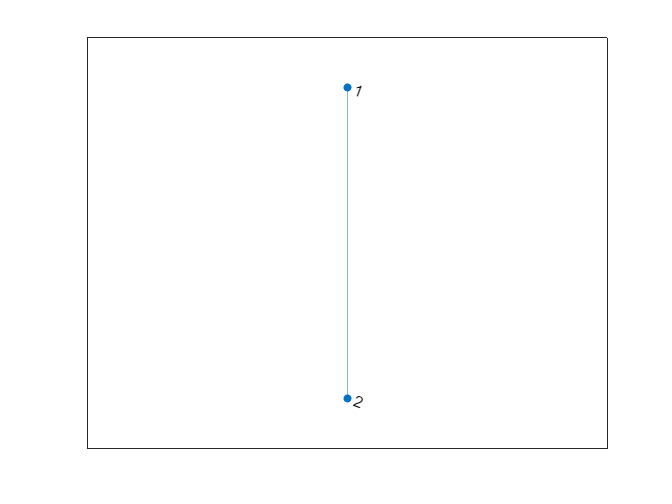


puzzle = [5 0 0 0 0 0 0 0 3; 
    0 0 6 0 0 9 2 5 0; 
    7 0 0 0 4 0 0 0 0; 
    0 0 0 0 0 0 8 0 0; 
    0 2 0 9 0 0 0 0 0; 
    0 0 5 0 0 2 6 1 0; 
    6 0 0 7 0 0 1 3 0; 
    0 0 0 0 0 1 0 0 8;
    0 0 3 0 0 0 0 0 9];

A= [zeros(81)]; % thsi is the adjacency matrix for the graph
for i = 1 : 81
    for j = 1 : 81
        if(floor((i-1)/9) == floor((j-1)/9) && i~=j) % connect all the nodes on the same row of the sudoku
            A(i,j) = 1;
        end
        if (mod(i,9) == mod(j,9) && i~=j) % connect all the nodes on the same column of the sudoku
            A(i,j) = 1;
        end
        if (floor((mod(i,9) - 1)/3) == floor((mod(j,9)- 1)/3) && i~=j) % connect all the nodes in the same subgrid of the sudoku
            if(floor((i-1)/9) <= 2)
                if(floor((j-1)/9) <= 2)
                    A(i,j) = 1;
                end
            elseif (floor((i-1)/9) <= 5)
                if((floor((j-1)/9) <=5) && (floor((j-1)/9) >= 3))
                    A(i,j) = 1;

                end
            elseif(floor((j-1)/9) >= 6)
                A(i,j) =1;
            end
        end
    end
end

A = max(A, A'); % i need symmetric matrix because the graph have only bidirectional edges

Sudoku_Graph1 = graph(A);


I will using the object Node_sudoku and whit this logic i can understand what Nodes are editable or not.


node_data = repmat(Node_sudoku(0, 1), 81, 1); % i allocate 1 array for the data in the graph

for i = 1:9
    for j = 1:9
        idx = (i - 1) * 9 + j;% linear index that reads rows and column
        if(puzzle(i,j) ~= 0)
            node_data(idx) = Node_sudoku(puzzle(i,j), 1);
        else
            node_data(idx) = Node_sudoku(puzzle(i,j), 0);
        end
    end
end

Sudoku_Graph1.Nodes.Data = node_data;


To simplify and understand the mechanism, I start with a **small graph of just 2 nodes**, and then scale the same logic to a full Sudoku board.




A2 = [0 1;
    1 0];
A2 = max (A2, A2');


Sudoku_Graph = graph(A2);

plot(Sudoku_Graph);

Try an example of a 2 sudoku cell, both is editable.

node_data_example = repmat(Node_sudoku(0,1),2,1);

node_data_example(1) = Node_sudoku(0,0);
node_data_example(2) = Node_sudoku(0,0);

Sudoku_Graph.Nodes.Data = node_data_example;

To rapresent in a correct way all the possible number in every cell I need 4 Q-bits for every node

tot_nodes = numnodes(Sudoku_Graph) * 4; % this *4 because I have 4 bits in every nodes
tot_edges = numedges(Sudoku_Graph);

gates = []; % I use that to increase the number of gate for the circuit

To simplify and understand the mechanism, I start with a **small graph of just 2 nodes**, and then scale the same logic to a full Sudoku board.

For each edge in the graph (i.e., each constraint between connected nodes), I:

- **Compare the 4 qubits** of the two connected nodes using XOR gates.

- Store the results in **helper qubits**, one for each bit comparison. Each edge will therefore use 4 helper qubits.

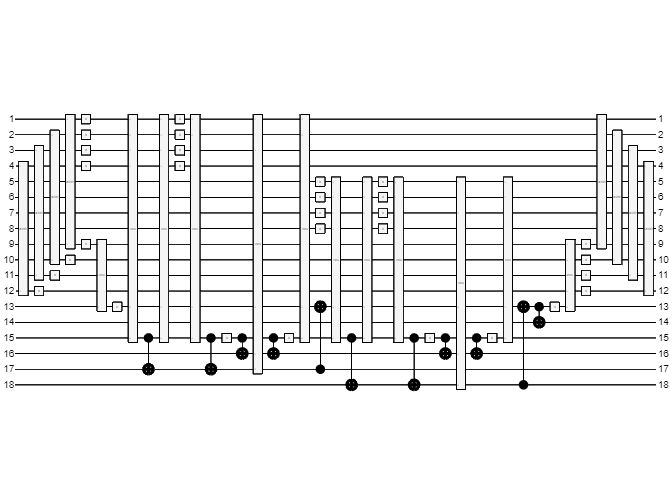

for k = 1:tot_edges
    Node_start = Sudoku_Graph.Edges.EndNodes(k,1) * 4; %this number rapresent the last Qbit of the current node
    Node_end = Sudoku_Graph.Edges.EndNodes(k,2) * 4;
    for y = 0:3

        gates = [gates; 
        compositeGate(xorGate,[(Node_start - y),(Node_end - y),(tot_nodes + (k*4) -y)])];
    end
end

Then, I verify if **all helper qubits for an edge are 0**, meaning both nodes have the same value — which violates the Sudoku rule. I want to detect and mark such cases:

- I apply **X gates** to invert the helper qubits.

- If all inverted helpers are 1, I apply a **multi-controlled CNOT** (mcx) to a target qubit, indicating an invalid configuration.

for m = (tot_nodes+1) : (tot_nodes + tot_edges*4)
    gates = [gates; xGate(m)]; % I apply the X gate to all helper Qbits
end
off_set_target = 1; % I need this offset to calculate the number of multiple cnot target Qbit 
for i = (tot_nodes+1) : 4 : (tot_nodes + tot_edges*4)
    gates = [gates;
        mcxGate([i,i+1,i+2,i+3],(tot_nodes + (tot_edges*4) + off_set_target),[])]; % apply the multiple cnot on helper Qbits

ans = "(-1-6.9389e-18i) * |1000001000000-0000>"

    off_set_target = off_set_target + 1;
end


if the last tot_edges number of Qbit are |0> this is the correct answer  and i need to apply phase inversion, to do that I can use the same logic of helper qubit, I apply a xgate and I use a multiple cnot. But before that I need to verify another constraints, in particular in the Grover's  Algorithm I use a combination of all possible solution whit same probability for every nodes, to do that we will use an H gate in every 4 Qbits of every nodes, but whit this idea I need to exclude the solution whit |0000> or 10 in binary ... (all the number from 10 to 15 that I create whit hadamar Gate but I can use in the solution of a 9X9 sudoku).


First_target_Qbit = tot_nodes + tot_edges * 4 +1;
Last_Qbit = First_target_Qbit + tot_edges;
Target_Qbit_Gates = [];


ans = "(1+2.9035e-16i) * |1000100000000-0000>"

for i = First_target_Qbit : (Last_Qbit -1)
    Target_Qbit_Gates = [Target_Qbit_Gates, i];
    gates = [gates;
        xGate(i)]; % Apply an Xgate to compare the target whit a multiple cnot
end



I need to consider if the value of the combination that I will do of the 4 Qbits is more than 9 or is 0, if this happen I need to consider the combination incorrect, so basicaly I need to canghe the taget Qbit if the conbination is not accetable ( from now the target Qbit become helper Qbit).

First of all I need to consider the |0000> combination, so if the oracle say yes to  specific conbination, I need to change this situation if one of the input is |0000>, to do that for every 4Qbit I apply if: the helper Qbit is 1 (so the two nodes are different), and I have |0000> in one of the number I need to consider this case wrong, so i just apply an Xgate on the four number Qbits and a multiple cnot gate on: number Qbits, the helper Qbit, and if they are all 1 I apply a not on the helper.

To do that I need an Ancillar Qbit, becaus I can't use the helper qbit in the CNOT as a control and target at the same time, I temporary "wrote" the result of the Cnot in an ancillar Qbit that is numbered as Last_Qbit + 1, and I will use this as a control Qbit for a Cnot gate whit another Qbit as a target (This Qbit will be after the Last_Qbit and I will have 1 for every node of the sudoku Graph), I use this another ancillar Qbit because I need to verify another constrains (is the number >9 ?) .

To mantein all possible Qbit in the same starting value I use the same gate in opposite order.


count_editable_node = 0; % I use this to know how much Qbit I need for the quantum circuit

ans = "(1-3.7817e-16i) * |1111000000001-0010>"


for i = 4 : 4 : tot_nodes
    offset = mod((i/4),2);
    if(offset == 1)
        Helper_Qbit = tot_nodes+ (tot_edges*4) +(i/4); % I use the offset to refer for every Helper Qbit that refer for one edge compare
    end
    if(Sudoku_Graph.Nodes.Data(i/4).State == 0)
        count_editable_node = count_editable_node + 1;

ans = "(1-6.0021e-16i) * |1101001000001-0010>"

        gates = [gates;xGate(i);xGate(i-1);xGate(i-2);xGate(i-3)];
        gates = [gates; mcxGate([i,(i-1),(i-2),(i-3),(Helper_Qbit)],Last_Qbit+1,[])];
        gates = [gates; cxGate(Last_Qbit + 1,Last_Qbit + 2 +(i/4))];
        gates = [gates; mcxGate([i,(i-1),(i-2),(i-3),(Helper_Qbit)],Last_Qbit+1,[])]; % return on the starting state for the Ancilla Qbit
        gates = [gates;xGate(i);xGate(i-1);xGate(i-2);xGate(i-3)];
        

What I need to consider is all the number >9 in binary, they are:

- |1010> = 10

- |1001> = 11

- |1100> = 12

- |1101> = 13

- |1110> = 14

- |1111> = 15

As I can see all this possibilities start whit 1 and whit a simple logic analisys I can say that: if I see for every node |abcd> the combination is unaccetable if: (a AND (a AND b OR c )) is equal to 1, so I just need to implement this in quantum gate.

I use a mcnot gate as an AND, for the or I just use an Xgate and a Cnot gate.

I also need to reuse some ancillar Qbit os I invert the gate at the end.

I apply the result of this operation on the same target Qbit we I were using in |0000> option, if this Qbit will be 1 I will aplly an Xgate on the helper Qbit, so I just need a Cnot in the end.

        gates = [gates; mcxGate([(i-3),(i-2),Helper_Qbit],Last_Qbit+1,[])]; % a AND b
        gates = [gates; cxGate(Last_Qbit +1,Last_Qbit +2 + (i/4)); xGate(Last_Qbit +1)]; % apply an X on lst +1 because if this is 0 I need to verify if a and c = 1
        gates = [gates; cxGate(Last_Qbit + 1,Last_Qbit +2)];
        gates = [gates; mcxGate([(Last_Qbit +2), (i-3),(i-1), Helper_Qbit],(Last_Qbit + 2 + (i/4)),[])];
        % return to starting state
        gates = [gates; cxGate(Last_Qbit + 1,Last_Qbit +2); xGate(Last_Qbit +1)];
        gates = [gates; mcxGate([(i-3),(i-2),Helper_Qbit],Last_Qbit+1,[])];
        % the last cnot on helper Qbit
        gates = [gates; cxGate(Last_Qbit + 2 + (i/4),Helper_Qbit)];
    end
end


Some considearation before go ahead:

- I can use the same target during the current node verification in the two cases 0 and >9 because if the node is 0 can't be >9 and if it is >9 can't be 0.

- I can reuse 2 ancillar Qbits because evry iteration I always restor the strating state

- every time I evaluate one node I need to verify if the Helper Qbit of his edge is 1 because for example I have |0000> and |1111> I need to change only 1 tome the helper. 

- Using this idea of oracle I couldn't have the same start and end value for every Qbit, because the helper can be different, but all the Qbit refer to the node value will be the equal to the start condition on the oracle gate.

Now I can apply the multiple cnot, if the answeare is yes i will have on the  last Qbit equal to |1>, if the answeare is incorrect I will have |0>, to have the phase inversion I just need to have |-> as a starting value of the Last_Qbit. Now I can apply a multiple cnot gate whit all the helper Qbits as a Control Qbits and the last Qbit as a target, after that i can create the oracle circuit.

gates = [gates; mcxGate(Target_Qbit_Gates,Last_Qbit,[])];

oracle = quantumCircuit(gates,Last_Qbit + 2 + count_editable_node);
oracle.Name = "Oracle";


ans =     "0.25 * |00000111> +
     0.25 * |00010111> +
     0.25 * |00100111> +
     0.25 * |00110111> +
     0.25 * |01000111> +
     0.25 * |01010111> +
     0.25 * |01100111> +
     0.25 * |01110111> +
     0.25 * |10000111> +
     0.25 * |10010111> +
     0.25 * |10100111> +
     0.25 * |10110111> +
     0.25 * |11000111> +
     0.25 * |11010111> +
     0.25 * |11100111> +
     0.25 * |11110111>"


oracle.Gates = [oracle.Gates; 
                flip(oracle.Gates(1:(tot_edges*4 + tot_edges*4 + tot_edges*2)))];

plot(oracle)

What i need to do now, is to verify if the oracle work whit some example. If every node have a 4 bit string i can understand if they are an accetable value or not.

Correct example, I want phase inversion: Node 1: 1000, Node 2: 0010


Valid_Sequence = "1000001000000-0000";
Valid_Input_State = quantum.gate.QuantumState(Valid_Sequence);
formula(Valid_Input_State);


Valid_Simulation = simulate(oracle,Valid_Input_State);
formula(Valid_Simulation)

Now try whit incorrect example: Qbit 1: 1000, Qbit 2:1000

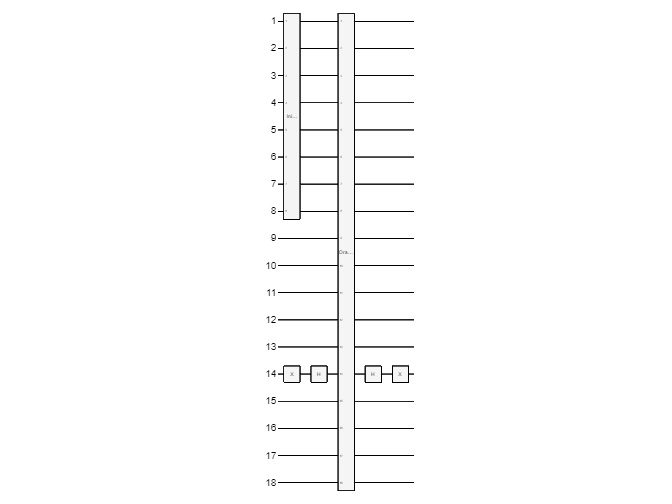


Invalid_Sequence = "1000100000000-0000";
Invalid_Input_State = quantum.gate.QuantumState(Invalid_Sequence);

formula(Invalid_Input_State);


ans =     "(0.25+4.9873e-18i)  * |000001110000100010> +
     (-0.25-2.0871e-18i) * |000101110000000000> +
     (-0.25-5.5132e-17i) * |001001110000000000> +
     (-0.25-4.6539e-17i) * |001101110000000000> +
     (-0.25-3.361e-18i)  * |010001110000000000> +
     (-0.25+6.5052e-19i) * |010101110000000000> +
     (-0.25-5.5132e-17i) * |011001110000000000> +
     (0.25+1.0885e-16i)  * |011101110000000000> +
     (-0.25+4.597e-17i)  * |100001110000000000> +
     (-0.25-1.0842e-18i) * |100101110000000000> +
     (0.25+2.6671e-17i)  * |101001110000100010> +
     (0.25+3.4423e-17i)  * |101101110000100010> +
     (0.25-6.1908e-17i)  * |110001110000100010> +
     (0.25-7.5786e-17i)  * |110101110000100010> +
     (0.25-1.3433e-16i)  * |111001110000100010> +
     (0.25-6.0661e-17i)  * |111101110000100010>"


Invalid_Simulation = simulate(oracle,Invalid_Input_State);
formula(Invalid_Simulation)

This constrains seems to work correctly.

Now try an invalid sequence whit 15 and 0 as an input


Invalid_Sequence2 = "1111000000000-0000";
Invalid_Input_State2 = quantum.gate.QuantumState(Invalid_Sequence2);
formula(Invalid_Input_State2);

Invalid_Simulation2 = simulate(oracle,Invalid_Input_State2);
formula(Invalid_Simulation2)

As I can see a valid sequance of two different nodes whit 2 invalid value is seen as an incorrect option from the oracle.

I can also try whit another example that have 2 different value and just one is > that 9

Invalid_Sequence3 = "1101001000000-0000";
Invalid_Input_State3 = quantum.gate.QuantumState(Invalid_Sequence3);
formula(Invalid_Input_State3);

Invalid_Simulation3 = simulate(oracle,Invalid_Input_State3);
formula(Invalid_Simulation3)

Whis this example I can say that apparently the oracle work correctly and follow the constrains.

I need to use a diffuser code to have the inversion around the mean for all the Qbits that rapresent the value of every nodes, I can use a function to do that.

What I need to think now is how to inizialize all the Qbits refers of the nodes. I start visit the graph and if I find an editable value I apply four H gate on the corrisponding Qbit, on other hands I just copy the correct value in binary, to do that I use an Xgate where I need.

In this case is usefull to have a quad of H gate


triple_H_InnerGates = [hGate(1:4)];
triple_H_Gate = quantumCircuit(triple_H_InnerGates,Name="TripleH");

gates_processing = [];

I use the objects in every node to understand what I need to do, before I change the value of the second node in the graph (in this way I can see the two possibilites: editable or not).

Sudoku_Graph.Nodes.Data(2).Qbit = dec2bin(7,4);
Sudoku_Graph.Nodes.Data(2).State = 1;

for i = 1 : (tot_nodes/4)
    Current_Node_Object = Sudoku_Graph.Nodes.Data(i);
    Current_Value = Current_Node_Object.Qbit;
    Current_Edit = Current_Node_Object.State;


If the object is not editable I just convert the value in binary and using some ASCII proprieties I convert in an array that help me to know if I need to apply or not the Xgate

    if(Current_Edit == 1)
        Current_vector_value = Current_Value - '0'; % I convert the string example "010" in a vector [010], this because in ASCII '1'-'0' = 1
        for j = 1:4
            if(Current_vector_value(j) == 1)
                qbit_index = (i-1)*4 + j;
                gates_processing = [gates_processing;
                    xGate(qbit_index)]; % apply the xgate on the right Qbit if the vector value is 1
            else
                continue
            end
        end


If the object is editable I need to apply an H gate on every Qbits

    else
        gates_processing = [gates_processing;
            compositeGate(triple_H_Gate,[(i*4),((i*4)-1),((i*4)-2),((i*4)-3)])];
    end
end

Now try whit an example to verify if this work correctly.

inizializer = quantumCircuit(gates_processing,tot_nodes);
inizializer.Name = "Inizializer";

Inizilize_simulation = simulate(inizializer,"00000000");
formula(Inizilize_simulation, Basis="Z")

As I can see I have all possible combination on Qbit 1-4 and seem always the right value on Qbit 5-8

After this example I want to verify if the oracle work correcltly after the inizializer , in this case whit 7 on the second node, the combination will be:

- (1,7), in binary: |00010111>

- (2,7), in binary: |00100111>

- (3,7), in binary: |00110111>

- (4,7), in binary: |01000111>

- (5,7), in binary: |01010111>

- (6,7), in binary: |01100111>

- (8,7), in binary: |10000111>

- (9,7), in binary: |10010111>

The first step is to inizialize the Last_Qbit whit |->, to do that I just apply an X gate end an H gate.

tot_Qbits = Last_Qbit + 2 + count_editable_node;
number_iteration = 1;
gates_lastExample = [];

for i = 1 : number_iteration
    gates_lastExample = [gates_lastExample; xGate(Last_Qbit); hGate(Last_Qbit)];
    gates_lastExample = [gates_lastExample; compositeGate(inizializer,1:tot_nodes) ; compositeGate(oracle,1 : tot_Qbits)];
    gates_lastExample = [gates_lastExample; hGate(Last_Qbit); xGate(Last_Qbit)];
end


last_example = quantumCircuit(gates_lastExample,tot_Qbits);
plot(last_example)
simulation_LastExample = simulate(last_example);
formula(simulation_LastExample, Basis="Z")

I have the correct phase inversion.

Creating a full-scale simulation of Grover's algorithm to solve an entire Sudoku puzzle is currently impractical due to the extremely high computational cost. However, as demonstrated through simpler examples, by modeling the Sudoku grid as a graph and applying the oracle logic defined in the live script, Grover's algorithm can indeed be used as a valid approach to solve Sudoku problems.